# Problema3 

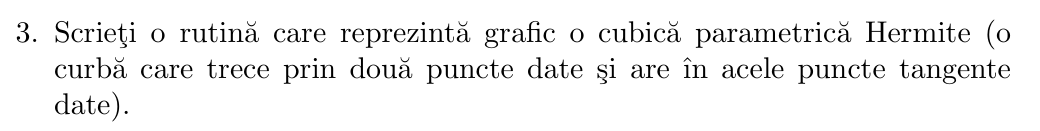

function [X, Y] = cubicHermite2D(P0, P1, T0, T1, N)
% CUBICHERMITE2D - Calculează punctele curbei Hermite cubice parametrică în 2D
%
% INPUT:
%   P0  - punctul de start al curbei, vector [x0, y0]
%   P1  - punctul de sfarsit al curbei, vector [x1, y1]
%   T0  - vectorul tangentei in P0, [dx0, dy0]
%   T1  - vectorul tangentei in P1, [dx1, dy1]
%   N   - (optional) numarul de puncte de discretizare (default: 200)
%
% OUTPUT:
%   X, Y - vectori 1 x N cu coordonatele punctelor de pe curbă

     % Daca nu este specificat numarul de puncte, folosim 200 ca default
    if nargin < 5
        N = 200;
    end

    % Vectorul parametrului t ∈ [0, 1], discretizat uniform
    t = linspace(0, 1, N);

    % Functiile de bază Hermite (forma standard)
    h1 = 2*t.^3 - 3*t.^2 + 1;      % baza pentru P0
    h2 = -2*t.^3 + 3*t.^2;         % baza pentru P1
    h3 = t.^3 - 2*t.^2 + t;        % baza pentru T0
    h4 = t.^3 - t.^2;              % baza pentru T1

    % Calculam coordonatele X și Y ale punctelor pe curba
    % Aplicam formula Hermite: H(t) = h1*P0 + h2*P1 + h3*T0 + h4*T1

    % Coordonata X a curbei:
    X = h1 * P0(1) + h2 * P1(1) + h3 * T0(1) + h4 * T1(1);

    % Coordonata Y a curbei:
    Y = h1 * P0(2) + h2 * P1(2) + h3 * T0(2) + h4 * T1(2);
end

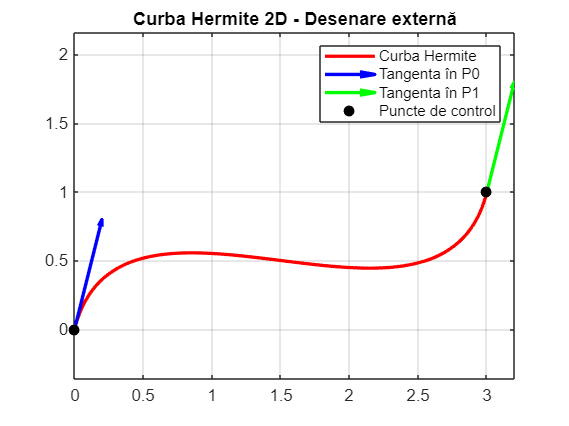

% Punctele și tangentele
P0 = [0, 0];
P1 = [3, 1];

T0 = [1, 4];
T1 = [1, 4];

% Apel funcție
[X, Y] = cubicHermite2D(P0, P1, T0, T1);

% Afișare grafic
figure;
plot(X, Y, 'r-', 'LineWidth', 2); hold on;
quiver(P0(1), P0(2), T0(1), T0(2), 0.2, 'b', 'LineWidth', 2);
quiver(P1(1), P1(2), T1(1), T1(2), 0.2, 'g', 'LineWidth', 2);
plot([P0(1), P1(1)], [P0(2), P1(2)], 'ko', 'MarkerFaceColor', 'k');
legend('Curba Hermite', 'Tangenta în P0', 'Tangenta în P1', 'Puncte de control');
title('Curba Hermite 2D - Desenare externă');
axis equal;
grid on;